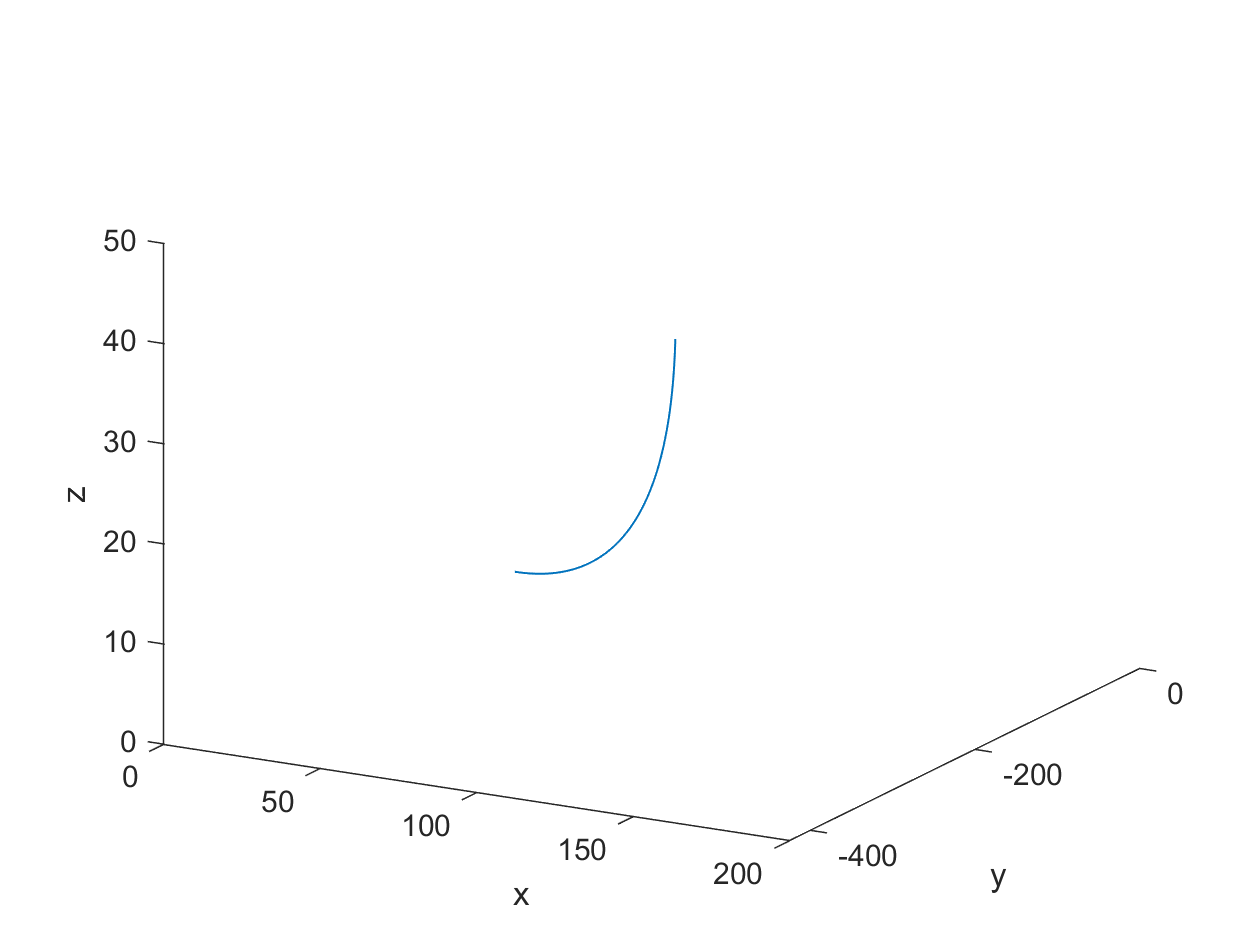

% Define constants
g = 9.81; % Acceleration due to gravity
m = 10; % Mass of the rocket
Fthrust = 20; % Thrust force of the rocket
Fdrag = 0.1; % Drag force on the rocket

% Define initial conditions
x0 = 0; % Initial x position
y0 = 0; % Initial y position
z0 = 0; % Initial z position
vx0 = 10; % Initial x velocity
vy0 = 0; % Initial y velocity
vz0 = 0; % Initial z velocity

% Define time range for simulation
t0 = 0; % Start time
tf = 10; % End time
dt = 0.1; % Time step
t = t0:dt:tf; % Time range for simulation



% Solve differential equations using ode45
y0 = [x0, y0, z0, vx0, vy0, vz0]; % Initial conditions
[t,y] = ode45(@rocketDynamics,t,y0);

% Plot results
plot3(y(:,1),y(:,2),y(:,3)); % Position in 3D space
xlabel('x');
ylabel('y');
zlabel('z');